clear all;
clc;

pir = 18.6e-6;
esp_receive = 0.09;
esp_transmit = 0.26;
deep_sleep = 30e-6;
hiber = 0.0000025;

tempo_rx = 1;
tempo_tx = 1;
tempo_ativo_rx = tempo_rx/3600;
tempo_ativo_tx = tempo_tx/3600;
tempo_ativo = tempo_ativo_rx + tempo_ativo_tx;

i = 1;

for k = 1:1:20
    
    consumo_pir = pir*24;
    consumo_esp_tx(k) = esp_transmit*24*tempo_ativo_tx*k;
    consumo_esp_rx(k) = esp_receive*24*tempo_ativo_tx*k;
    consumo_esp_24rx(k) = esp_receive*24;
    consumo_esp_deep = deep_sleep*24*(1-2*tempo_ativo);
    consumo_esp_hiber = hiber*24*(1-2*tempo_ativo);
    
    consumo_total_deep = consumo_pir+consumo_esp_rx+consumo_esp_tx+consumo_esp_deep;
    consumo_total_hiber = consumo_pir+consumo_esp_rx+consumo_esp_tx+consumo_esp_hiber;
    consumo_esp_24ligada = consumo_esp_tx + consumo_esp_24rx + consumo_pir;
    
    autonomia_hiber = 10./consumo_total_hiber;
    autonomia_deep = 10./consumo_total_deep;
    autonomia_esp_24ligada = 10./consumo_esp_24ligada;
   
    
    i = i+1;
end

k = 1:1:20;
figure(1)
plot(k,autonomia_deep,'b');
% hold on
% 
% plot(k,autonomia_hiber,'r');
% hold off

legend("Consumo com deep sleep", "Consumo com Hibernation","Consumo com ESP sempre à escuta");

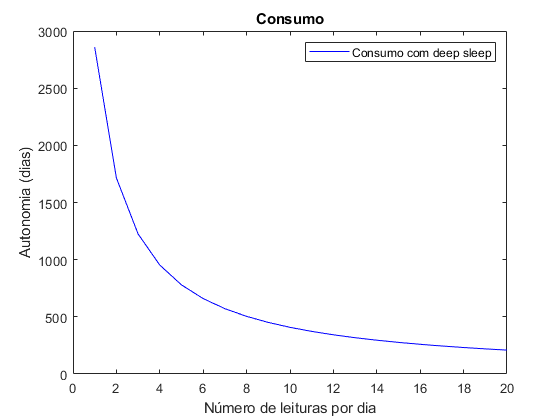

title("Consumo")
ylabel("Autonomia (dias)");
xlabel("Número de leituras por dia");

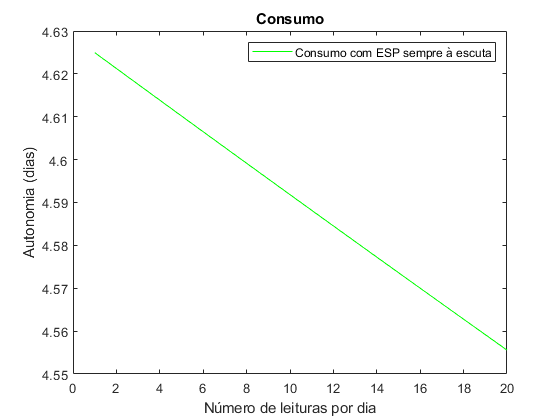


plot(k,autonomia_esp_24ligada,'g');

legend("Consumo com ESP sempre à escuta");
title("Consumo")
ylabel("Autonomia (dias)");
xlabel("Número de leituras por dia");